% 11 jan 2018

% EXERCISE 1

%A
%A
syms q1 real
syms q2 real
syms q3 real
syms q4 real
syms q5 real
syms q6 real
syms q7 real

syms a3 positive real
syms a4 positive real
syms a6 positive real

syms d1 positive real
syms d3 positive real
syms d5 positive real
syms d7 positive real

alpha = [-pi/2, pi/2, -pi/2,-pi/2,-pi/2,-pi/2,0];
a=[0,0,a3,a4,0,a6,0];
d=[d1,0,d3,0,d5,0,d7];
theta=[q1,q2,q3,q4,q5,q6,q7];

table=[alpha',a',d',theta']

$$table = \left(\begin{array}{cccc} -\frac{\pi }{2} & 0 & d_{1} & q_{1}\\ \frac{\pi }{2} & 0 & 0 & q_{2}\\ -\frac{\pi }{2} & a_{3} & d_{3} & q_{3}\\ -\frac{\pi }{2} & a_{4} & 0 & q_{4}\\ -\frac{\pi }{2} & 0 & d_{5} & q_{5}\\ -\frac{\pi }{2} & a_{6} & 0 & q_{6}\\ 0 & 0 & d_{7} & q_{7} \end{array}\right)$$

%plot the robot
%Note: it has different format respect to Sveva's DHMatrix function
l_a = 0.1

l_a = 0.1000

l_d = 0.3

l_d = 0.3000


a_no_sym = double(subs(a, {a3,a4,a6}, {l_a,l_a,l_a}));
alpha_no_sym = alpha;
d_no_sym = double(subs(d, {d1,d3,d5,d7}, {l_d,l_d,l_d,l_d}));
theta_no_sym = double(subs(theta, {q1,q2,q3,q4,q5,q6,q7}, {0,0,0,0,0,0,0}));

DHTable=[a_no_sym', alpha_no_sym',d_no_sym',theta_no_sym']

DHTable =          0   -1.5708    0.3000         0
         0    1.5708         0         0
    0.1000   -1.5708    0.3000         0
    0.1000   -1.5708         0         0
         0   -1.5708    0.3000         0
    0.1000   -1.5708         0         0
         0         0    0.3000         0


joints = 'RRRRRRR';
robot_model = build_robot_model(joints, DHTable);


config = homeConfiguration(robot_model)%build_configuration(robot_model, array_joint_values);

config = 1×7 struct array with fields:
    JointName
    JointPosition


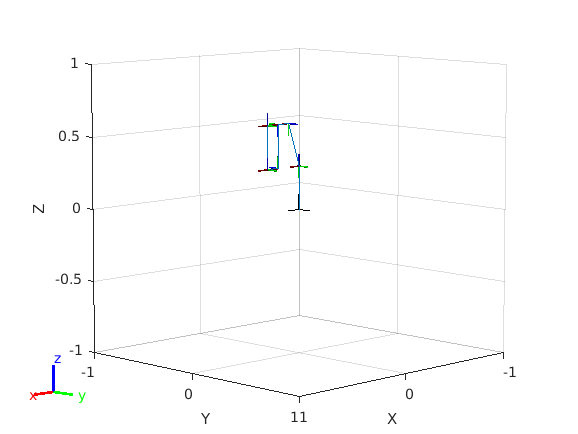


show(robot_model, config);

%B
[T, A] = DHMatrix(table);
A0_1=A{1}

$$A0\_1 = \left(\begin{array}{cccc} \cos\left(q_{1}\right) & 0 & -\sin\left(q_{1}\right) & 0\\ \sin\left(q_{1}\right) & 0 & \cos\left(q_{1}\right) & 0\\ 0 & -1 & 0 & d_{1}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

A1_2=A{2}

$$A1\_2 = \left(\begin{array}{cccc} \cos\left(q_{2}\right) & 0 & \sin\left(q_{2}\right) & 0\\ \sin\left(q_{2}\right) & 0 & -\cos\left(q_{2}\right) & 0\\ 0 & 1 & 0 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

A2_3=A{3}

$$A2\_3 = \left(\begin{array}{cccc} \cos\left(q_{3}\right) & 0 & -\sin\left(q_{3}\right) & a_{3}\,\cos\left(q_{3}\right)\\ \sin\left(q_{3}\right) & 0 & \cos\left(q_{3}\right) & a_{3}\,\sin\left(q_{3}\right)\\ 0 & -1 & 0 & d_{3}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

A3_4=A{4}

$$A3\_4 = \left(\begin{array}{cccc} \cos\left(q_{4}\right) & 0 & -\sin\left(q_{4}\right) & a_{4}\,\cos\left(q_{4}\right)\\ \sin\left(q_{4}\right) & 0 & \cos\left(q_{4}\right) & a_{4}\,\sin\left(q_{4}\right)\\ 0 & -1 & 0 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

T